% Preamble
clc;
clear;
close all;

This is a 1-second clip of velvet noise, at a sample rate of 44,100Hz. The control `Nd` changes the amount of impulses per second (the density of the velvet noise).

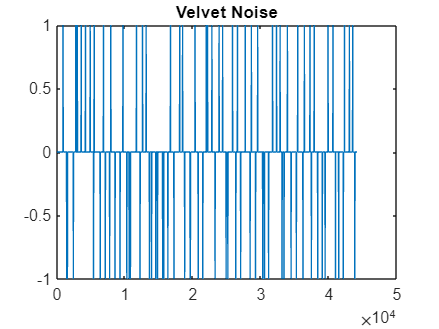

Nd =90;
Fs = 44100; % Sample rate
v = velvet(Nd, Fs, Fs);
plot(v);
title('Velvet Noise');

Next, let's load in a sample of a trumpet being played.

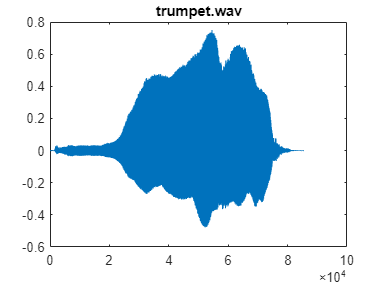

trumpet = audioread('trumpet.wav');
plot(trumpet);
title('trumpet.wav');

When we convolve the trumpet sound with a velvet noise signal, we get a signal that sounds like an extended version of the original.

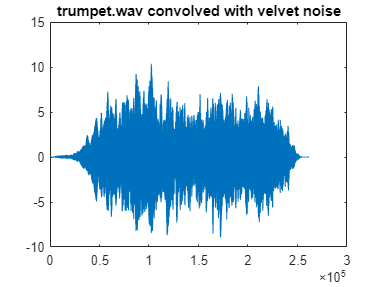

% Convolve with velvet noise
seconds = 4;
v = velvet(Nd, Fs, Fs*seconds);
trumpet_extended = conv(trumpet, v);
plot(trumpet_extended);
title('trumpet.wav convolved with velvet noise');

soundsc(trumpet_extended, Fs);

Another way to create extended (or endless) versions of sounds is to use a high-order linear-prediction filter. We can use the `lpc` function in Matlab to derive filter coefficients (and gain) for an FIR filter, which we then use as coefficients for an all-pole IIR filter, then use that filter on white noise.

Here's an example of that with a one-second clip of airplane cabin noise.

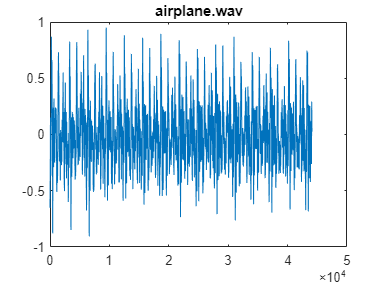

airplane = audioread('airplane.wav');
plot(airplane);
title('airplane.wav');

 
soundsc(airplane, Fs);

Note that the order of the filter has to be fairly high $\left(\approx 10000\right)$ in order for this method to work.

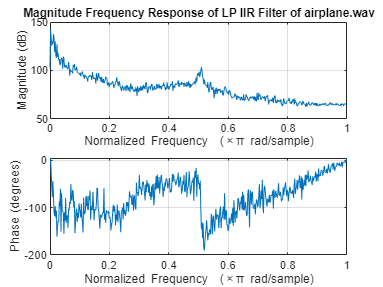

order = 9070;
[a, g] = lpc(airplane, order);
freqz(1, a*g);
title('Magnitude Frequency Response of LP IIR Filter of airplane.wav');

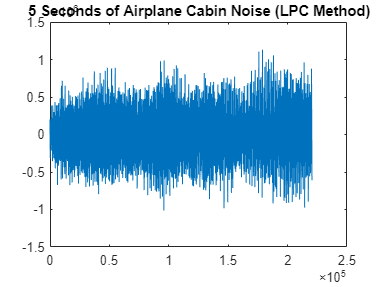

airplane_extended = filter(1, a*g, randn(Fs*5, 1));
plot(airplane_extended);
title('5 Seconds of Airplane Cabin Noise (LPC Method)');

soundsc(airplane_extended, Fs);

Notice that as the order of the filter is decreased, the output signal sounds increasingly like white noise.

Convolving with velvet noise of a sufficient density achieves a similar result.

Nd = 2205;
airplane_vnc = vnc(Nd, Fs, Fs*5, airplane);
soundsc(airplane_vnc, Fs);

Another method for extending sounds is to use the frequency-domain representation and multiply with white noise. This is functionally equivalent to convolution in the time domain, but can be more computationally efficient for long signals.

First, we pad the input signal with zeros, up to our desired output length, in this case, 5 seconds.

X = fft([airplane; zeros(Fs*5-length(airplane), 1)]);

We then take the FFT of our padded input signal and the FFT of white noise and multiply them in the frequency domain.

V = fft(randn(Fs*5, 1));
Y = X.*V;

Finally, we take the IFFT of the output signal to get our result.

y = ifft(Y);
soundsc(y, Fs);

This process can be further simplified by using the fact that convolution with white noise is approximately equal to changing the phase response of the input signal to a random angle while leaving the magnitude response unchanged.

% Generate uniformly-distributed values between -pi and pi
rgen = @(N) arrayfun(@(x) rand()*2*pi - pi, 1:N);
% Set the angle of a complex exponential
set_angle = @(x, a) abs(x) * exp(1i*a);
r = rgen(length(X)/2 - 1);
r2 = flip(r);
theta_r = [0 r 0 -r2];
Z = zeros(length(X), 1);
for i = 1:length(X)
    Z(i) = set_angle(X(i), theta_r(i));
end
Z = ifft(Z);
soundsc(Z, Fs);